kappa_ext = 1.2323e6;
kappa_tot = kappa_ext + .22653e6; %kappa_int = 0.2265MHz. These values correspond to ng = 0 and phi = 0 for Jules' sample in March 2021 small fridge
% kerr = 0;
kerr = -.5e6;
detunings = linspace(-5*kappa_tot, 5*kappa_tot, 1000);
omega_0 = 5.7851e9; % in Hz. 
h = 6.626e-34; % just h, not hbar since omega_0 is in Hz

power_input_start_dBm = -65 -81; 
power_input_stop_dBm = -55 -81; % 81dB is approx fridge attenuation. 
power_input_start_watts = 1e-3.*10.^(power_input_start_dBm/10);
power_input_stop_watts = 1e-3.*10.^(power_input_stop_dBm/10);

% power_input_in_watts = linspace(power_input_start_watts, power_input_stop_watts, 5);
% power_input_in_dBm = 10*log10(power_input_in_watts/1e-3);

power_input_in_dBm = linspace(power_input_start_dBm, power_input_stop_dBm, 100);
power_input_in_watts = 1e-3.*10.^(power_input_in_dBm/10);

power_input_in_numbers = power_input_in_watts/h/omega_0;
kerr = kerr/1e6;
kappa_ext = kappa_ext /1e6;
kappa_tot = kappa_tot/ 1e6;
detunings = detunings/ 1e6;
power_input_in_numbers = power_input_in_numbers/1e6;
[detunings_array, power_input_array] = meshgrid(detunings, power_input_in_numbers);
amp_roots = zeros([size(detunings_array),3]);

for i = 1: size(detunings_array,1)
    for j = 1: size(detunings_array,2)
        amp_roots(i,j,:) = roots([kerr^2, -2*kerr.*detunings_array(i,j), (detunings_array(i,j).^2 + kappa_tot^2 / 4),...
            -kappa_ext * power_input_array(i,j)]);
    end
end

amp_roots(imag(amp_roots) ~=0) = 0;

detunings_array_reps = repmat(detunings_array, [1, 1, 3]);
s11 = ((detunings_array_reps - kerr .* amp_roots) - 1i*(kappa_tot -...
2*kappa_ext)/2)./((detunings_array_reps - kerr .* amp_roots) -1i*kappa_tot/2);
s11(amp_roots == 0) = 5;

% check_detuning_number = randi(length(detunings)/2)
% check_power_input = randi(length(power_input_in_numbers))
check_detuning_number = 394

check_detuning_number = 394

check_power_input = 3

check_power_input = 3

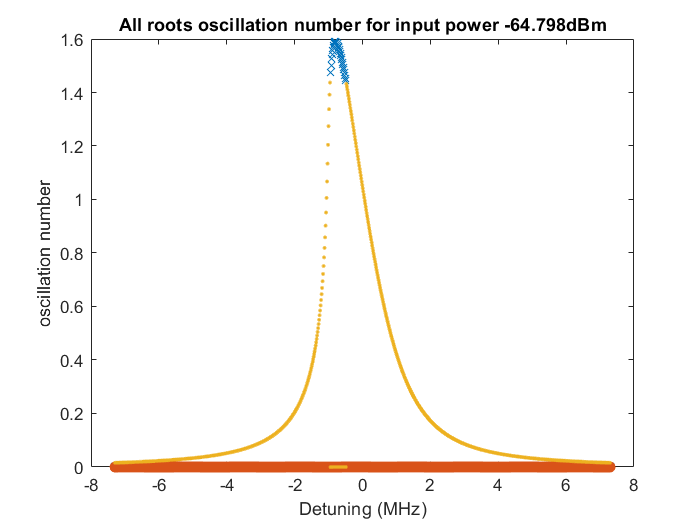

% amp_roots(check_power_input,check_detuning_number,:)
% check_value = kerr^2 .* amp_roots(check_power_input,check_detuning_number,:).^3 - 2*kerr.*detunings_array(check_power_input,check_detuning_number) .* amp_roots(check_power_input,check_detuning_number,:).^2  +...
%     (detunings_array(check_power_input,check_detuning_number)^2 + kappa_tot^2/4) .* amp_roots(check_power_input,check_detuning_number,:) -...
%     kappa_ext * power_input_array(check_power_input,check_detuning_number)
    
% i = randi(100)
% figure
% plot(detunings_array(check_power_input,:), amp_roots(check_power_input,:,1))
% xlabel('Detuning (Hz)')
% ylabel('oscillation number')
% title(['1st root oscillation number for input power ' num2str(power_input_in_dBm(i)) 'dBm'])
% 
% figure
% plot(detunings_array(check_power_input,:), amp_roots(check_power_input,:,2))
% xlabel('Detuning (Hz)')
% ylabel('oscillation number')
% title(['2nd root oscillation number for input power ' num2str(power_input_in_dBm(check_power_input)) 'dBm'])
% 
% figure
% plot(detunings_array(check_power_input,:), amp_roots(check_power_input,:,3))
% xlabel('Detuning (Hz)')
% ylabel('oscillation number')
% title(['3rd root oscillation number for input power ' num2str(power_input_in_dBm(check_power_input)) 'dBm'])

figure
plot(detunings_array(check_power_input,:), amp_roots(check_power_input,:,1),'x')
hold on
plot(detunings_array(check_power_input,:), amp_roots(check_power_input,:,2),'o')
plot(detunings_array(check_power_input,:), amp_roots(check_power_input,:,3),'.')
hold off
xlabel('Detuning (MHz)')
ylabel('oscillation number')
title(['All roots oscillation number for input power ' num2str(power_input_in_dBm(check_power_input) + 81) 'dBm'])

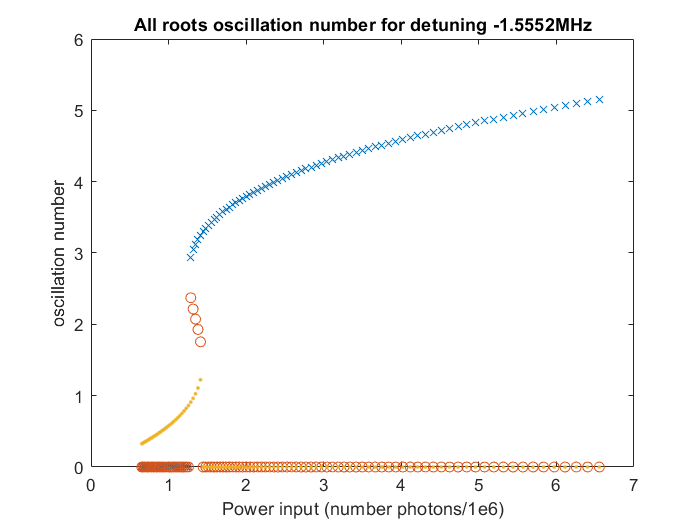


% figure
% plot(power_input_array(:,check_detuning_number), amp_roots(:,check_detuning_number,1))
% xlabel('Power input (number photons)')
% ylabel('oscillation number')
% title(['1st root oscillation number for detuning ' num2str(detunings(check_detuning_number)) 'MHz'])
% 
% figure
% plot(power_input_array(:,check_detuning_number), amp_roots(:,check_detuning_number,2))
% xlabel('Power input (number photons)')
% ylabel('oscillation number')
% title(['2nd root oscillation number for detuning ' num2str(detunings(check_detuning_number)) 'MHz'])
% 
% figure
% plot(power_input_array(:,check_detuning_number), amp_roots(:,check_detuning_number,3))
% xlabel('Power input (number photons)')
% ylabel('oscillation number')
% title(['3rd root oscillation number for detuning ' num2str(detunings(check_detuning_number)) 'MHz'])

figure
plot(power_input_array(:,check_detuning_number), amp_roots(:,check_detuning_number,1),'x')
hold on
plot(power_input_array(:,check_detuning_number), amp_roots(:,check_detuning_number,2),'o')
plot(power_input_array(:,check_detuning_number), amp_roots(:,check_detuning_number,3),'.')
hold off
xlabel('Power input (number photons/1e6)')
ylabel('oscillation number')
title(['All roots oscillation number for detuning ' num2str(detunings(check_detuning_number)) 'MHz'])

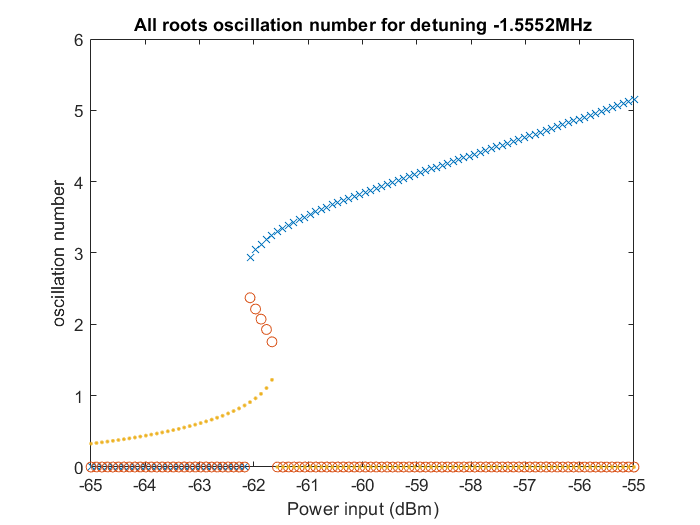


figure
plot(10*log10(power_input_array(:,check_detuning_number)*h*omega_0*1e6/1e-3) + 81, amp_roots(:,check_detuning_number,1),'x')
hold on
plot(10*log10(power_input_array(:,check_detuning_number)*h*omega_0*1e6/1e-3) + 81, amp_roots(:,check_detuning_number,2),'o')
plot(10*log10(power_input_array(:,check_detuning_number)*h*omega_0*1e6/1e-3) + 81, amp_roots(:,check_detuning_number,3),'.')
hold off
xlabel('Power input (dBm)')
ylabel('oscillation number')
title(['All roots oscillation number for detuning ' num2str(detunings(check_detuning_number)) 'MHz'])

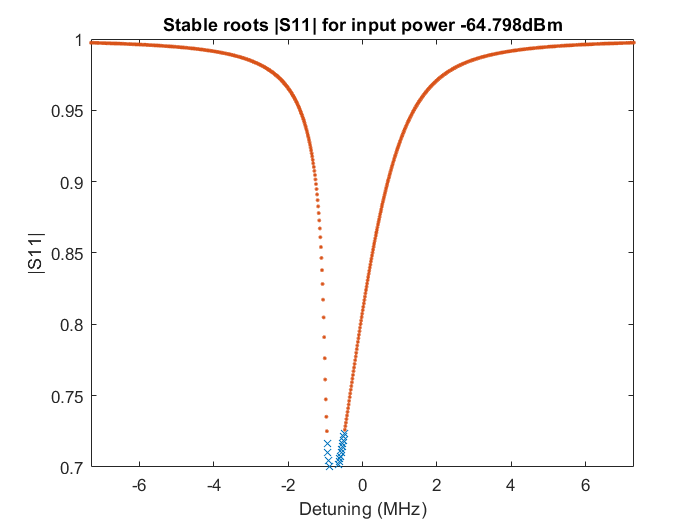


figure
plot(detunings_array(check_power_input,:), abs(s11(check_power_input,:,1)),'x')
hold on
% plot(detunings_array(check_power_input,:), abs(s11(check_power_input,:,2)),'o')
plot(detunings_array(check_power_input,:), abs(s11(check_power_input,:,3)),'.')
hold off
xlabel('Detuning (MHz)')
ylabel('|S11|')
axis([detunings(1) detunings(end) .7 1])
title(['Stable roots |S11| for input power ' num2str(power_input_in_dBm(check_power_input) + 81) 'dBm'])

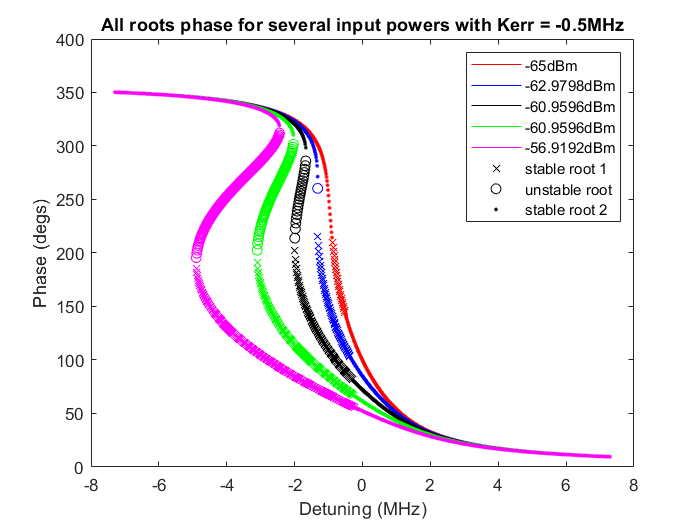

ans = -58.9394


figure
color_array = ['r', 'b', 'k', 'g', 'm'];
i = 1;
j = 1;
while i<100
    detunings_array_1 = detunings_array(i,:);
    s11_root_1_temp = s11(i,:,1);
    detunings_array_1 (s11_root_1_temp == 5) = [];
    s11_root_1_temp(s11_root_1_temp == 5) = [];
    
    detunings_array_2 = detunings_array(i,:);
    s11_root_2_temp = s11(i,:,2);
    detunings_array_2 (s11_root_2_temp == 5) = [];
    s11_root_2_temp(s11_root_2_temp == 5) = [];
    
    detunings_array_3 = detunings_array(i,:);
    s11_root_3_temp = s11(i,:,3);
    detunings_array_3 (s11_root_3_temp == 5) = [];
    s11_root_3_temp(s11_root_3_temp == 5) = [];
    
    root_1_color_prop = [color_array(j) 'x'];
    root_2_color_prop = [color_array(j) 'o'];
    root_3_color_prop = [color_array(j) '.'];
    plot(detunings_array_1, wrapTo360(angle(s11_root_1_temp)*180/pi),root_1_color_prop)%,'x')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + 81) 'dBm, root 1'])
    hold on
    plot(detunings_array_2, wrapTo360(angle(s11_root_2_temp)*180/pi),root_2_color_prop)%,'o')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + 81) 'dBm, root 2'])
    plot(detunings_array_3, wrapTo360(angle(s11_root_3_temp)*180/pi),root_3_color_prop)%,'.')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + 81) 'dBm, root 3'])
    xlabel('Detuning (MHz)')
    ylabel('Phase (degs)')
    title(['All roots phase for several input powers with Kerr = ' num2str(kerr) 'MHz'])
    i = i + 20;
    j = j + 1;
end
h = zeros(8,1);
h(1) = plot(nan, nan, 'r');hold on
h(2) = plot(nan, nan, 'b');
h(3) = plot(nan, nan, 'k');
h(4) = plot(nan, nan, 'g');
h(5) = plot(nan, nan, 'm');
h(6) = plot(nan, nan, 'kx');
h(7) = plot(nan, nan, 'ko');
h(8) = plot(nan, nan, 'k.');
legend (h, [num2str(power_input_in_dBm(1) + 81) 'dBm'], [num2str(power_input_in_dBm(21) + 81) 'dBm'], [num2str(power_input_in_dBm(41) + 81) 'dBm'],...
    [num2str(power_input_in_dBm(61) + 81) 'dBm'], [num2str(power_input_in_dBm(81) + 81) 'dBm'], 'stable root 1', 'unstable root', 'stable root 2')
hold off

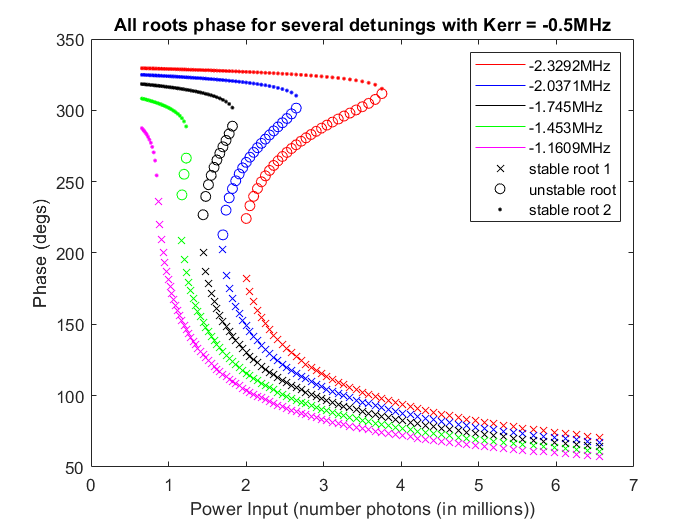


figure
color_array = ['r', 'b', 'k', 'g', 'm'];
i_start = 341;
i = i_start;
j = 1;
while i<i_start + 100
    power_input_array_temp_1 = power_input_array(:,i);
    s11_root_1_temp = s11(:,i,1);
    power_input_array_temp_1 (s11_root_1_temp == 5) = [];
    s11_root_1_temp(s11_root_1_temp == 5) = [];
    
    power_input_array_temp_2 = power_input_array(:,i);
    s11_root_2_temp = s11(:,i,2);
    power_input_array_temp_2 (s11_root_2_temp == 5) = [];
    s11_root_2_temp(s11_root_2_temp == 5) = [];
    
    power_input_array_temp_3 = power_input_array(:,i);
    s11_root_3_temp = s11(:,i,3);
    power_input_array_temp_3 (s11_root_3_temp == 5) = [];
    s11_root_3_temp(s11_root_3_temp == 5) = [];
    
    root_1_color_prop = [color_array(j) 'x'];
    root_2_color_prop = [color_array(j) 'o'];
    root_3_color_prop = [color_array(j) '.'];
    plot(power_input_array_temp_1, wrapTo360(angle(s11_root_1_temp)*180/pi),root_1_color_prop)%,'x')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + 81) 'dBm, root 1'])
    hold on
    plot(power_input_array_temp_2, wrapTo360(angle(s11_root_2_temp)*180/pi),root_2_color_prop)%,'o')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + 81) 'dBm, root 2'])
    plot(power_input_array_temp_3, wrapTo360(angle(s11_root_3_temp)*180/pi),root_3_color_prop)%,'.')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + 81) 'dBm, root 3'])
    xlabel('Power Input (number photons (in millions))')
    ylabel('Phase (degs)')
    title(['All roots phase for several detunings with Kerr = ' num2str(kerr) 'MHz'])
    i = i + 20;
    j = j + 1;
end
i = 341;
h = zeros(8,1);
h(1) = plot(nan, nan, 'r');hold on
h(2) = plot(nan, nan, 'b');
h(3) = plot(nan, nan, 'k');
h(4) = plot(nan, nan, 'g');
h(5) = plot(nan, nan, 'm');
h(6) = plot(nan, nan, 'kx');
h(7) = plot(nan, nan, 'ko');
h(8) = plot(nan, nan, 'k.');
legend (h, [num2str(detunings(i)) 'MHz'], [num2str(detunings(i +20)) 'MHz'], [num2str(detunings(i +40) ) 'MHz'],...
    [num2str(detunings(i +60)) 'MHz'], [num2str(detunings(i +80) ) 'MHz'], 'stable root 1', 'unstable root', 'stable root 2')
hold off